# Problem Set 4: Hypergraphs

**Submission: **submit a single PDF file to Canvas

**Due: **3/24/2022

**Questions: **Please post all questions to Piazza

**Name:**

**Collaborators:**

In this problem set we explore methods of constructing uniform hypergraphs. In the first exercise, you will propose your own method for constructing uniform hypergraphs from nonuniform data. Then, in the second exercise, you will use multi-correlation methods to construct a hypergraph and implement your method from exercise 1.

## Constructing a Uniform Hypergraph

Often data is non-uniform, and we have a set of vertices *V* and hyperedges of varying sizes. This occurs in social networks, information systems, chromosome conformation capture data, and many other systems where the size of each group interaction varries. When this occurs, there is not one definitive method for representing the non-uniform data as a tensor or uniform hypergraph.

Propose your own method to construct a tensor representation or *k-*uniform hypergraph representation of nonuniform data. Write cleanly and explain the motivation of your method and the advantages of your representation of nonuniform data.

**Solution:**

## Constructing Hypergraphs from Multi-correlation

In this problem, we will construct hypergraphs from time series data using the three multi-correlation methods above. The activity of 21 neurons was monitored over the course of a feeding experiment to generate a time series data set. Using the provided time series data,  the three methods of multi-correlation, we will construct a series of hypergraphs.

The code for this problem is currently set up to constructe a single hypergraph according to one multi-correlation method, and one value of *k*. To generate multiple hypergraphs, run all of the code in this section and save the constructed hypergraph to a new variable name. Then, rerun the code with a different value of *k* and type of multi-correlation.

**(a) **Compute all 3, 4, and 5-way multi-correlation coefficients among neurons using the time series data using each multi-correlation coefficient.

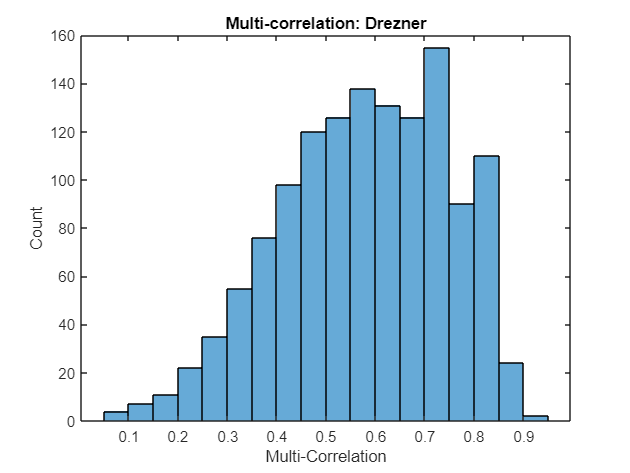

% Load data
load('Copy_of_mouse 44_fed_fasted_refed traces.csv')
D = Copy_of_mouse_44_fed_fasted_refed_traces;

% TODO: set value of k or number of vertices per hypergraph
k = 3; % Try 3, 4, and 5

% TODO: set the type of multi-correlation used
mcType = "Drezner"; % also try 'Wang' and 'Taylor'
[M, idxs] = HAT.multicorrelations(D, k, 'Drezner');
figure; histogram(M); xlabel('Multi-correlation');
ylabel('Count'); title("Multi-correlation: " + string(mcType))

**(b)** Set a threshold for the minimum multi-correlation coefficient that will indicate a hyperedge in your hypergraph.

thresh = 0.85;

**(c) **Construct *k*−uniform hypergraph objects from your 3, 4, and 5-way multi-correlaiton data.

m = find(M > thresh);            % Find idxs in M with value > thresh
hyperedges = idxs(m, :);    % Sets of vertices with measures > thresh are extracted
IM = HAT.hyperedge2IM(hyperedges);
HG = Hypergraph('IM', IM)

HG =   Hypergraph with properties:

             IM: [21×26 double]
    edgeWeights: [26×1 double]
    nodeWeights: [21×1 double]


**(d)** Apply your proposed method from Exercise 1 to construct a single hypergraph or tensor representation from the 3-uniform 4-uniform, and 5-uniform hypergraphs that you constructed in parts (a)-(c).

% TODO: Implement your proposed method from Problem 1
